A = magic(7)

A =     30    39    48     1    10    19    28
    38    47     7     9    18    27    29
    46     6     8    17    26    35    37
     5    14    16    25    34    36    45
    13    15    24    33    42    44     4
    21    23    32    41    43     3    12
    22    31    40    49     2    11    20



mean(A)

ans =     25    25    25    25    25    25    25


mean(A,2)

ans =     25
    25
    25
    25
    25
    25
    25


mean(A,'all')

ans = 25


median(A)

ans =     22    23    24    25    26    27    28


median(A,2)

ans =     28
    27
    26
    25
    24
    23
    22


A = [3 3 1 5; 0 0 1 1; 0 1 2 4]

A =      3     3     1     5
     0     0     1     1
     0     1     2     4



%doc mode
mode(A)

ans =      0     0     1     1


mode(A,2)

ans =      3
     0
     0


mode(A,'all')

ans = 1


min(A)

ans =      0     0     1     1


max(A)

ans =      3     3     2     5



%doc min
min(A,[], 2)

ans =      1
     0
     0


min(A,[], 'all')

ans = 0

A

A =      3     3     1     5
     0     0     1     1
     0     1     2     4


%doc var
var(A)

ans =     3.0000    2.3333    0.3333    4.3333


var(A,0)

ans =     3.0000    2.3333    0.3333    4.3333


var(A,0,2)

ans =     2.6667
    0.3333
    2.9167


var(A,0,'all')

ans = 2.7500


std(A)

ans =     1.7321    1.5275    0.5774    2.0817


std(A,0)

ans =     1.7321    1.5275    0.5774    2.0817


std(A,0,2)

ans =     1.6330
    0.5774
    1.7078


std(A,0,'all')

ans = 1.6583

Random Numbers

A

A = 1×5 single row vector
    0.3095    0.6846    0.2617    0.3275    0.2756


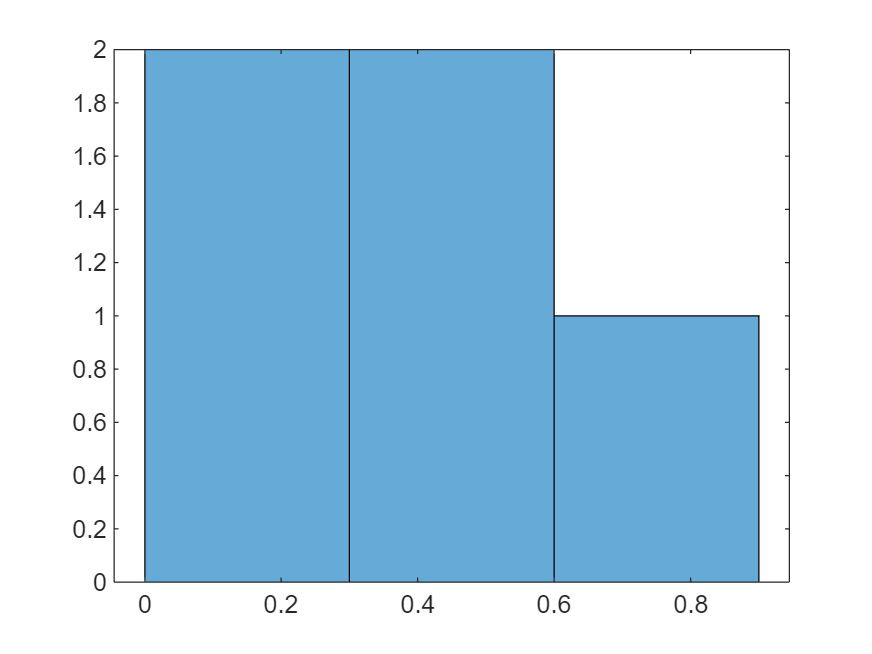

histogram(A)

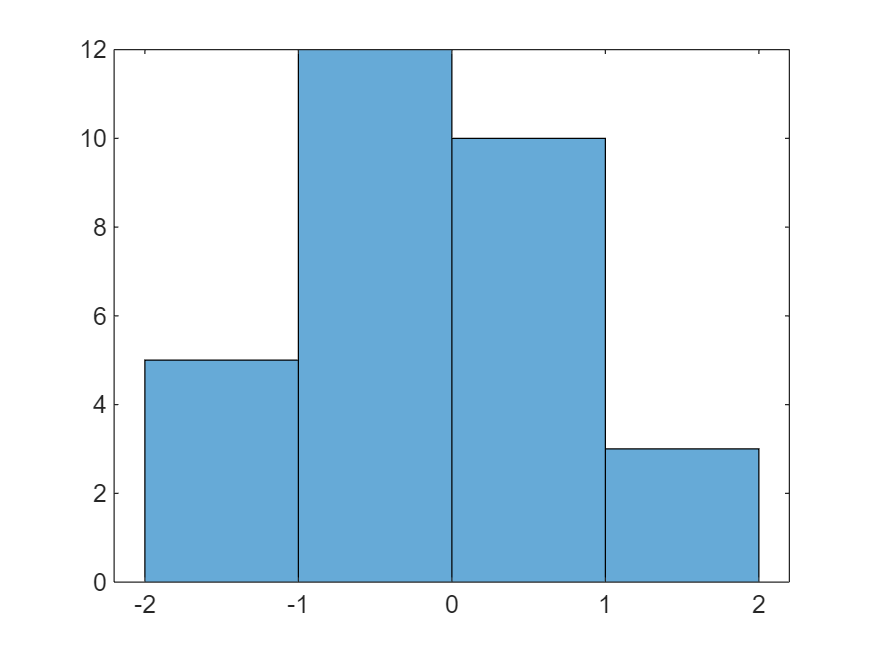


x = randn(30,1);
histogram(x)

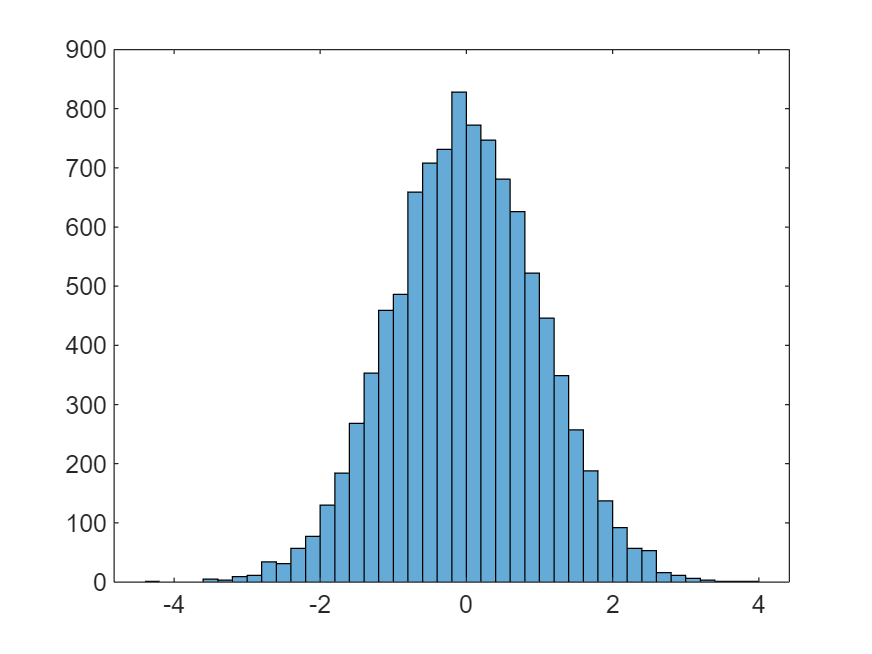



x = randn(10000,1);
histogram(x)


rand

ans = 0.8248

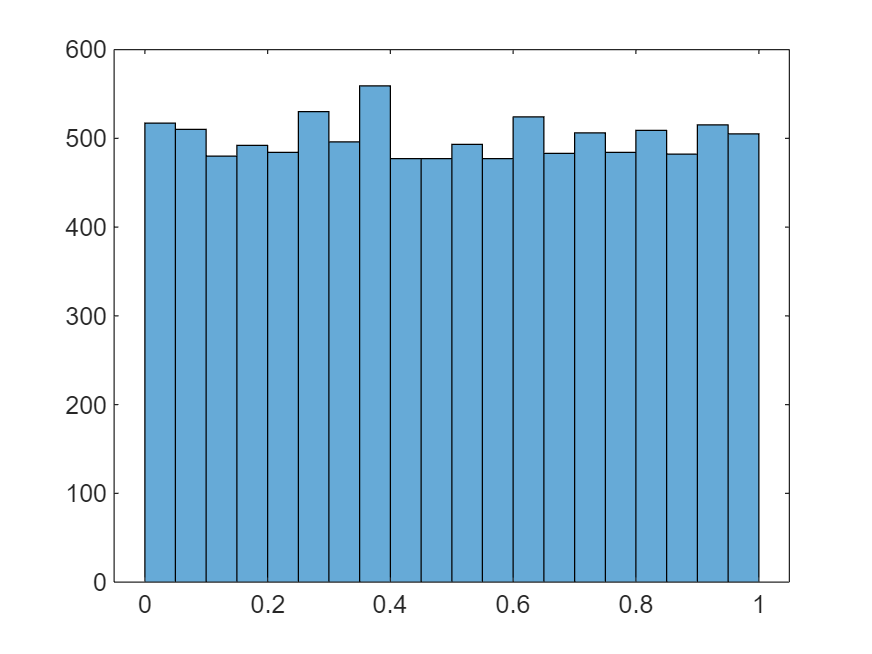

X = rand(10000,1);
histogram(X)


A = rand(1,5,'single')

A = 1×5 single row vector
    0.5866    0.6314    0.2900    0.6233    0.4132


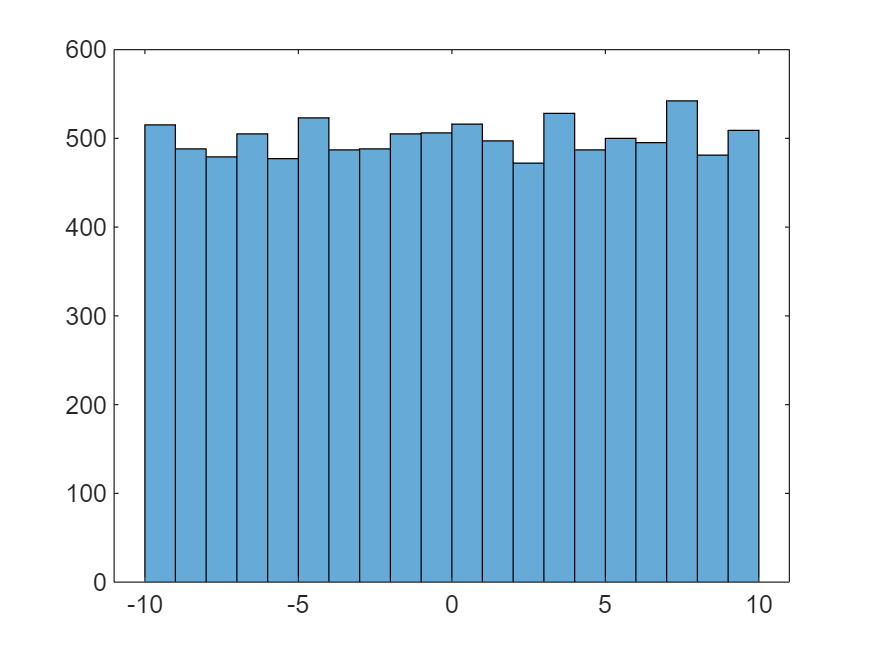


L = -10;
U = 10;

X = L + (U-L)*rand(10000,1);
histogram(X)

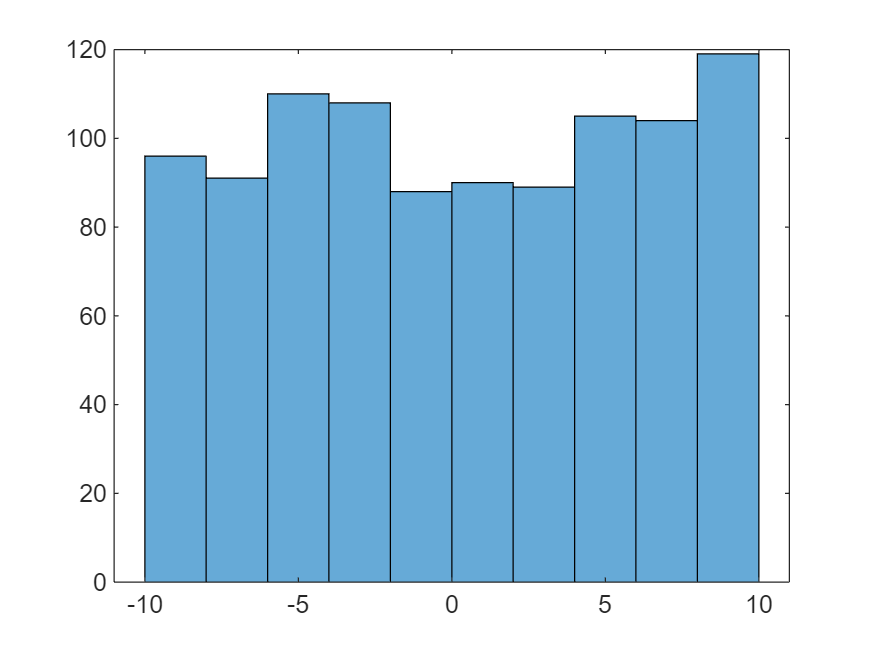


X2 = unifrnd(L,U,1000,1);
histogram(X2)


unifrnd(1,5)

ans = 1.5381

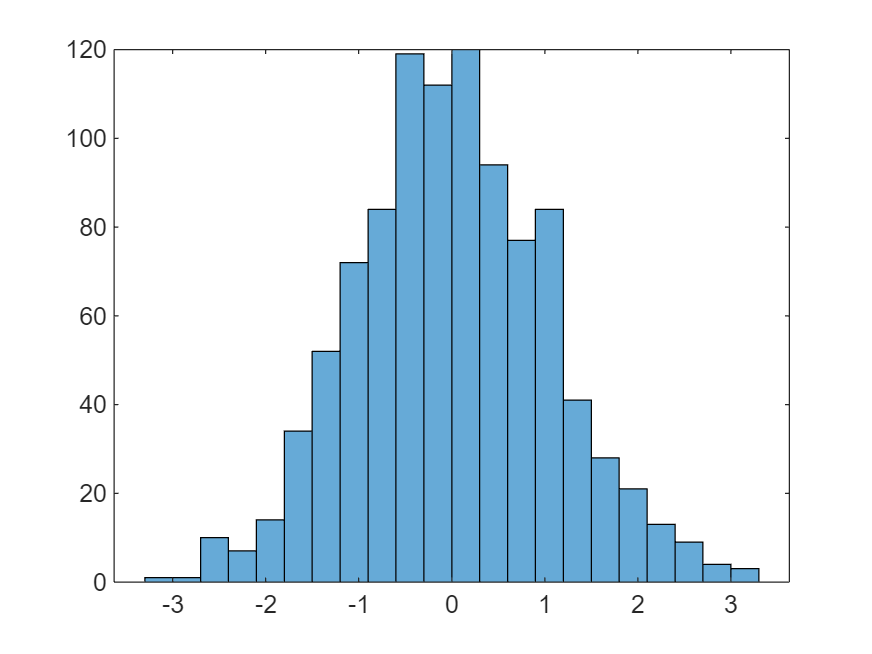


X = randn(1000,1);
histogram(X)

var(X)

ans = 1.0648

mean(X)

ans = 0.0140

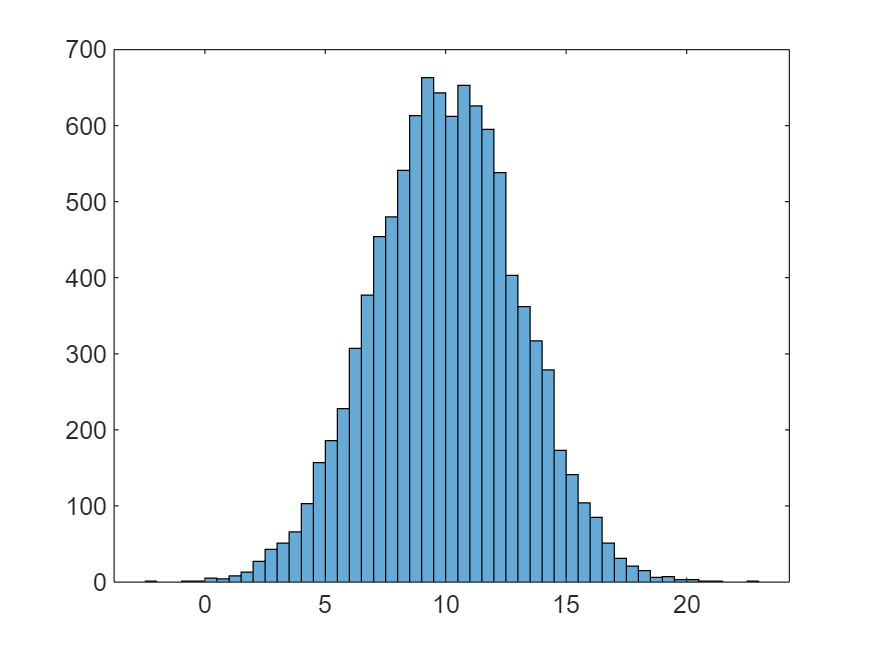


X2 = normrnd(10,3,10000,1);
histogram(X2)

var(X2)

ans = 8.9727

mean(X2)

ans = 10.0201

%doc randi
randi(10)

ans = 6

randi([-5,5])

ans = -3

randi([-5,5],10,2)

ans =     -4     4
    -1    -3
     5     4
    -3     4
     4    -2
    -3    -3
     5     0
    -5    -3
    -1    -5
     0     1



%doc randperm
randperm(6)

ans =      2     3     5     4     1     6


randperm(8,4)

ans =      4     2     6     5


randperm(3,3)

ans =      1     2     3



%doc randsample
randsample(8,4)

ans =      1
     8
     2
     3


randperm(8,4)

ans =      5     1     6     4


Multivariate Normal Distribution

%doc mvnrnd

mu = [2 3];
sigma = [1 0; 0 1]

sigma =      1     0
     0     1


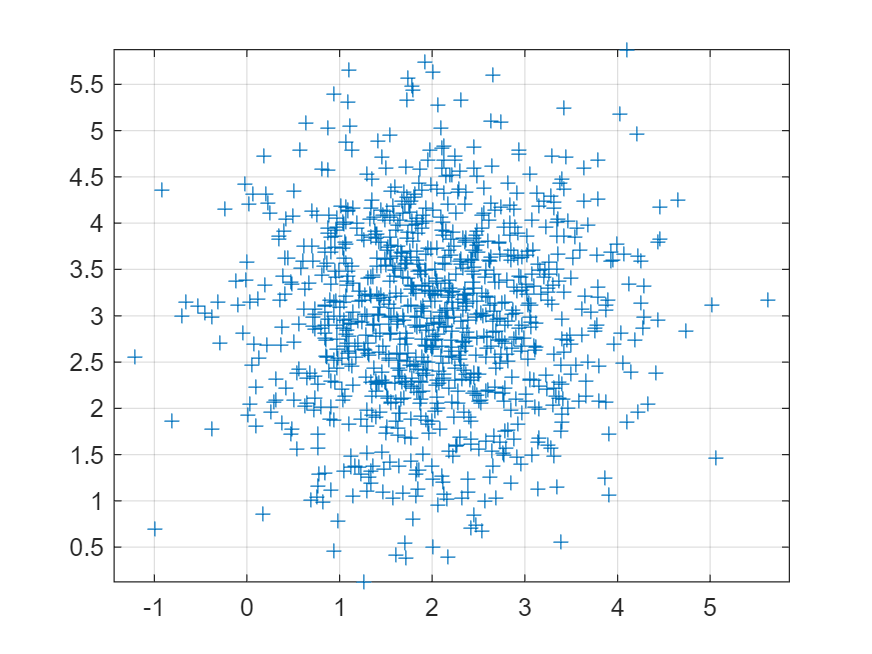

R = mvnrnd(mu, sigma, 1000);

plot(R(:,1),R(:,2),'+')
axis equal
grid on



mu = [2 3];
sigma = [1 0; 0 10]

sigma =      1     0
     0    10


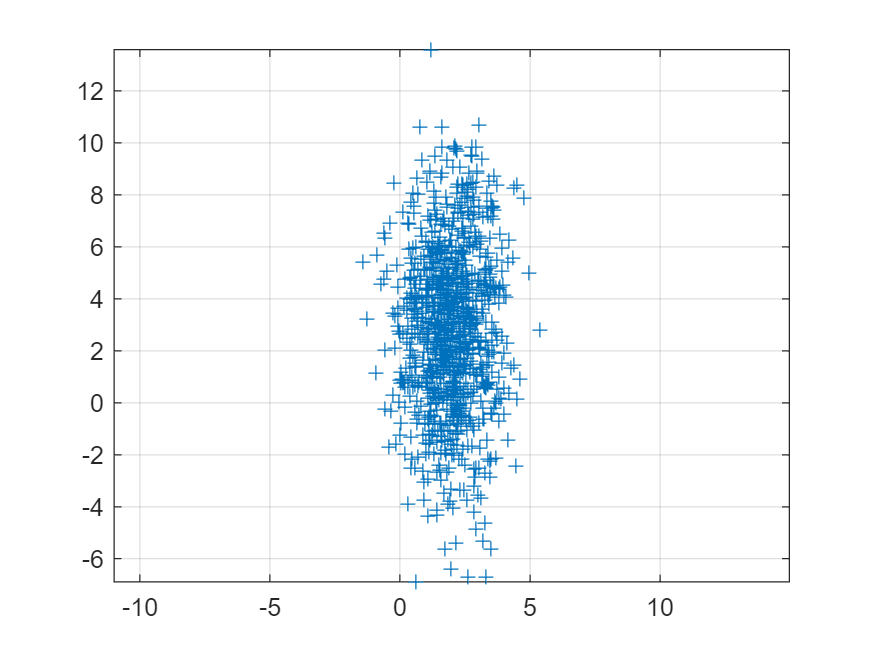

R = mvnrnd(mu, sigma, 1000);

plot(R(:,1),R(:,2),'+')
axis equal
grid on



mu = [2 3];
sigma = [1 1; 1 1.5]

sigma =     1.0000    1.0000
    1.0000    1.5000


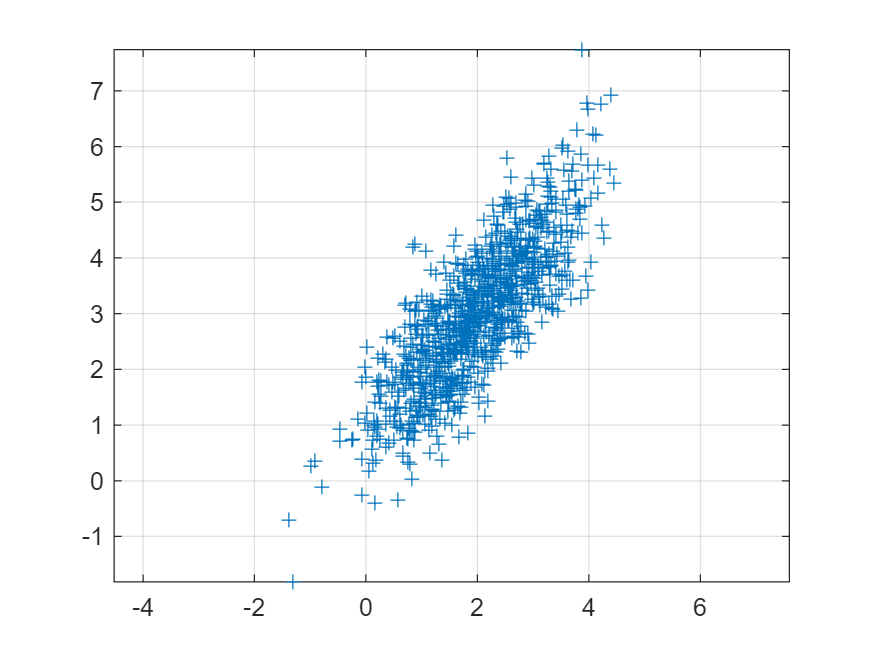

R = mvnrnd(mu, sigma, 1000);

plot(R(:,1),R(:,2),'+')
axis equal
grid on

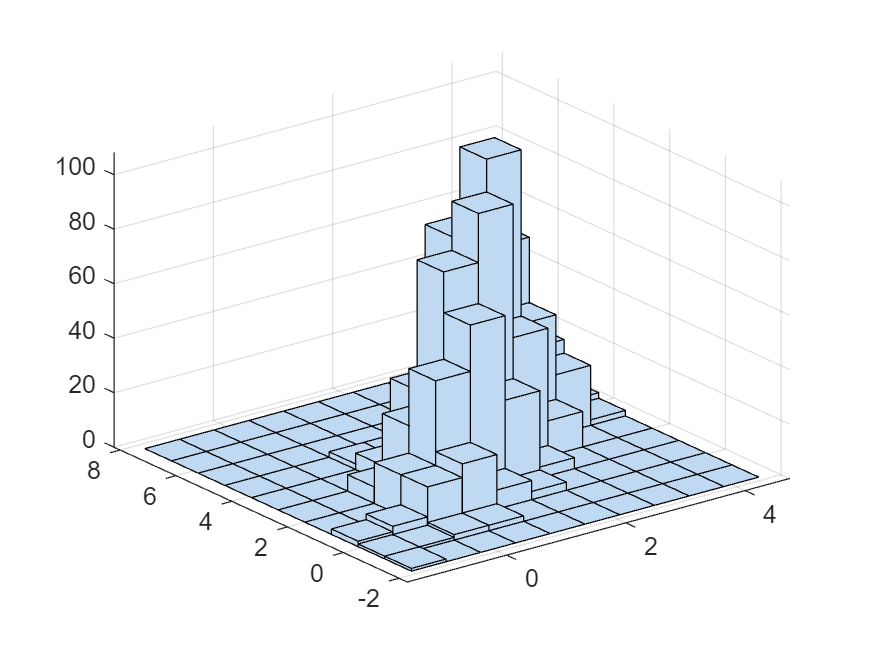


hist3(R)

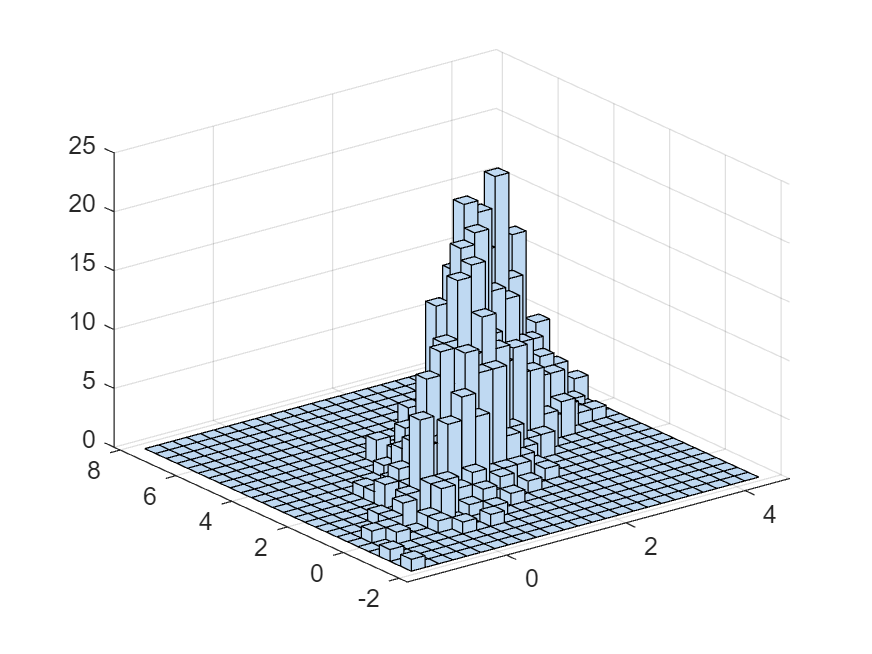

hist3(R,[25,25])

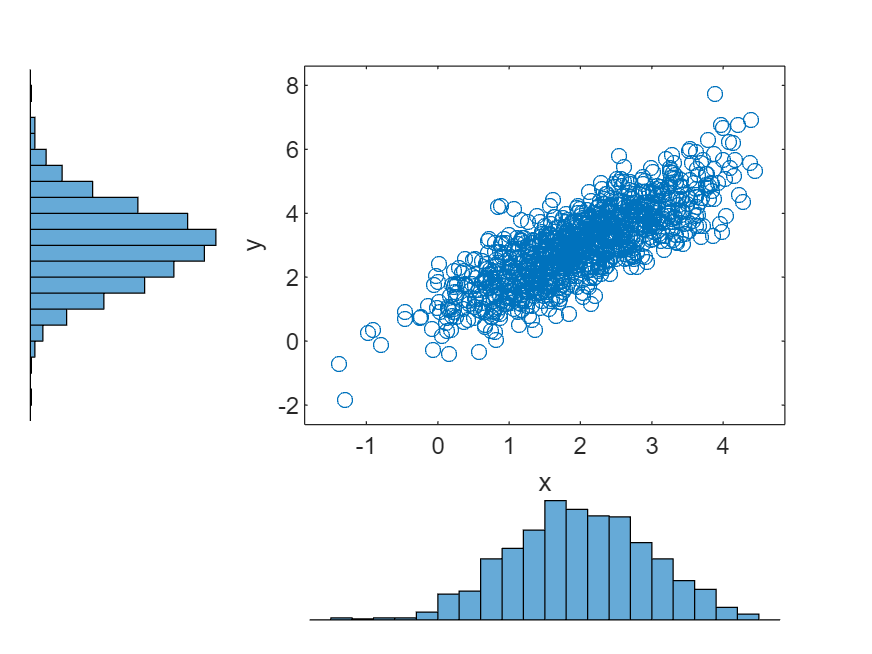

scatterhist(R(:,1),R(:,2))





mu = [2 3 4];
sigma = [1 0 0 ; 0 1 0; 0 0 1]

sigma =      1     0     0
     0     1     0
     0     0     2


R = mvnrnd(mu, sigma, 1000)

R =     1.3686    4.8331    4.5219
    2.6968    2.9176    4.1338
    2.2089    3.4839    5.6621
    1.6071    2.6834    5.2947
    3.1850    1.4090    6.4354
    4.0115    1.7591    3.3490
    1.3340    2.7094    4.4589
    3.0164    3.8044    2.6132
    3.3365    3.3435    2.6703
    0.3847    3.2608    3.7982


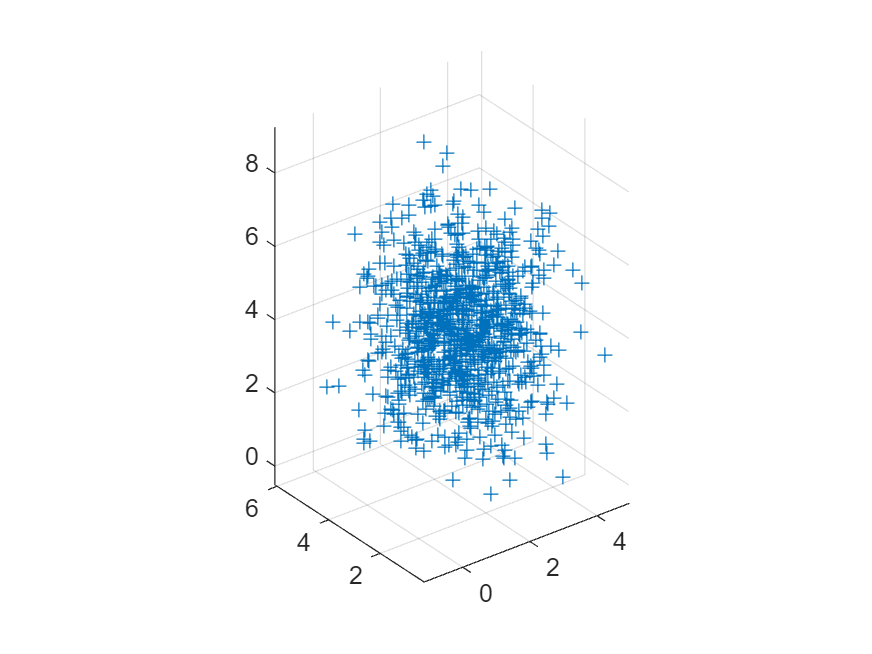


plot3(R(:,1),R(:,2),R(:,3),'+')
axis equal
grid on

mu = [2 3];
sigma = [3 0.5; 0.5 1]

sigma =     3.0000    0.5000
    0.5000    1.0000


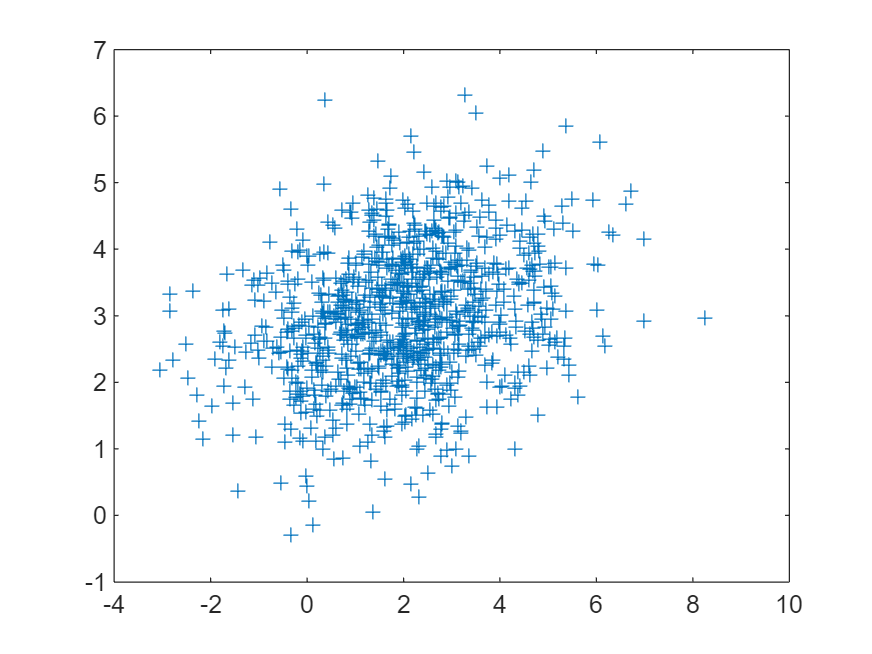

R = mvnrnd(mu, sigma, 1000);
plot(R(:,1),R(:,2),'+')



%doc corr
corr(R)

ans =     1.0000    0.2694
    0.2694    1.0000


cov(R)

ans =     2.8586    0.4525
    0.4525    0.9871


skewness(R)

ans =     0.0372    0.0124


x1 = randn(1,100000)

x1 =    -1.6110   -0.0085   -0.2465    0.8330   -1.3104   -2.0526    0.9506    1.4872   -1.3339   -0.2711   -0.6611   -0.8034   -1.5189   -0.7327    1.1676    0.7869    0.2044   -1.6779   -1.0094   -0.1972   -0.9178   -0.1691    0.6864   -0.4650   -0.3666   -0.0396   -0.8963   -1.2702   -1.0709   -0.9529   -1.2664   -0.4492    0.1953   -0.9089    0.2143    1.4255    1.4364   -1.1415    2.0680   -0.3573    1.2825   -1.5163   -1.3588    1.0283   -0.4068   -1.1056    0.4250   -0.7744    0.9660    1.4675


x2 = 3*randn(1,100000)

x2 =     0.0518    2.8432    5.8685    0.1335   -1.1801    0.8485    1.7716   -0.1987   -2.2391   -1.5199    0.9455    2.8358   -0.2617   -0.9848    3.5817    0.8675    0.6704   -0.6709   -3.5849   -2.2770    4.5811   -2.4021   -6.5653   -1.1814   -1.1828   -0.6683   -2.2608    2.6311   -1.8394   -0.5464    0.8850    0.3928    3.8649   -0.3201    3.7567    0.8388   -0.3073   -2.8519   -5.8432   -2.2826    0.7158    3.7937   -1.8535   -3.8608    0.2717    7.2287   -1.9255   -5.3402    0.0810   -2.8086


skewness(x1)

ans = -0.0094

skewness(x2)

ans = -0.0127



x = max(x1,x2)

x =     0.0518    2.8432    5.8685    0.8330   -1.1801    0.8485    1.7716    1.4872   -1.3339   -0.2711    0.9455    2.8358   -0.2617   -0.7327    3.5817    0.8675    0.6704   -0.6709   -1.0094   -0.1972    4.5811   -0.1691    0.6864   -0.4650   -0.3666   -0.0396   -0.8963    2.6311   -1.0709   -0.5464    0.8850    0.3928    3.8649   -0.3201    3.7567    1.4255    1.4364   -1.1415    2.0680   -0.3573    1.2825    3.7937   -1.3588    1.0283    0.2717    7.2287    0.4250   -0.7744    0.9660    1.4675


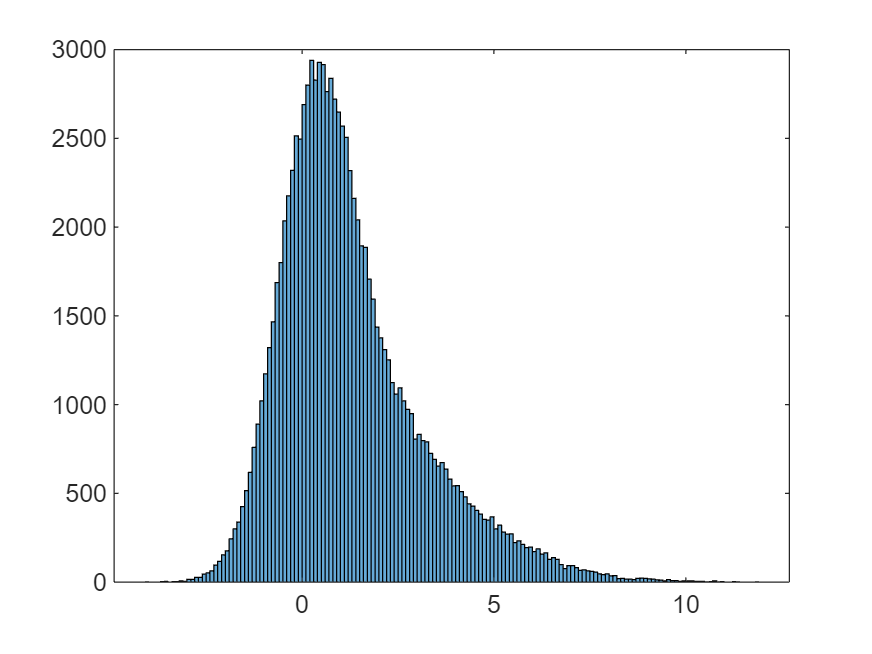

histogram(x)

skewness(x)

ans = 1.0885

x = randn(1,100000);
kurtosis(x)

ans = 2.9856

x = 20*randn(1,100000);
kurtosis(x)

ans = 3.0190



x1 = randn(1,100000);
x2 = 3*randn(1,100000);
x = max(x1,x2);

kurtosis(x)

ans = 4.5695

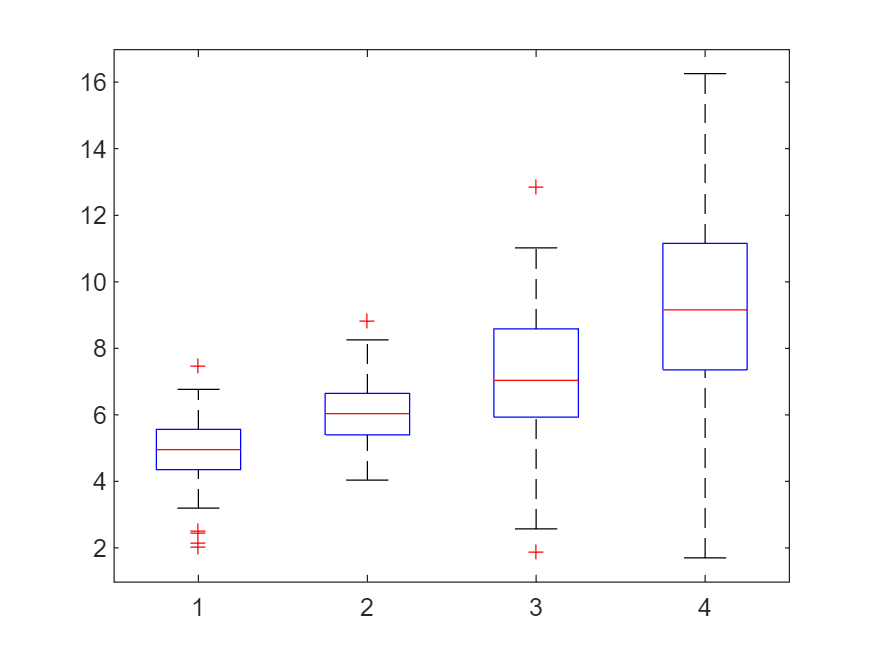

%doc boxplot

x1 = normrnd(5,1,100,1);
x2 = normrnd(6,1,100,1);
x3 = normrnd(7,2,100,1);
x4 = normrnd(9,3,100,1);

boxplot([x1, x2, x3, x4])

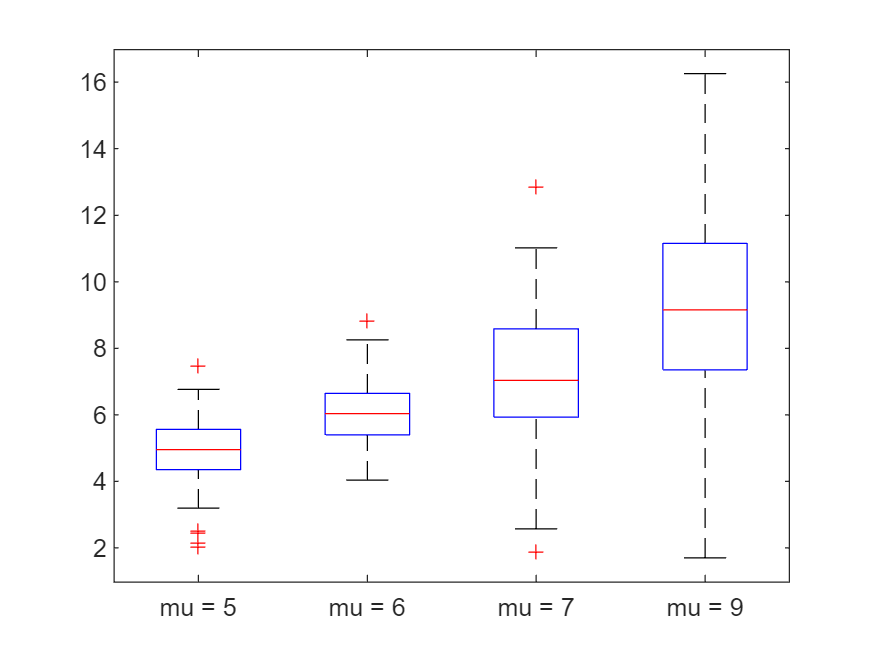


boxplot([x1, x2, x3, x4],'Labels', {'mu = 5', 'mu = 6', 'mu = 7', 'mu = 9'})

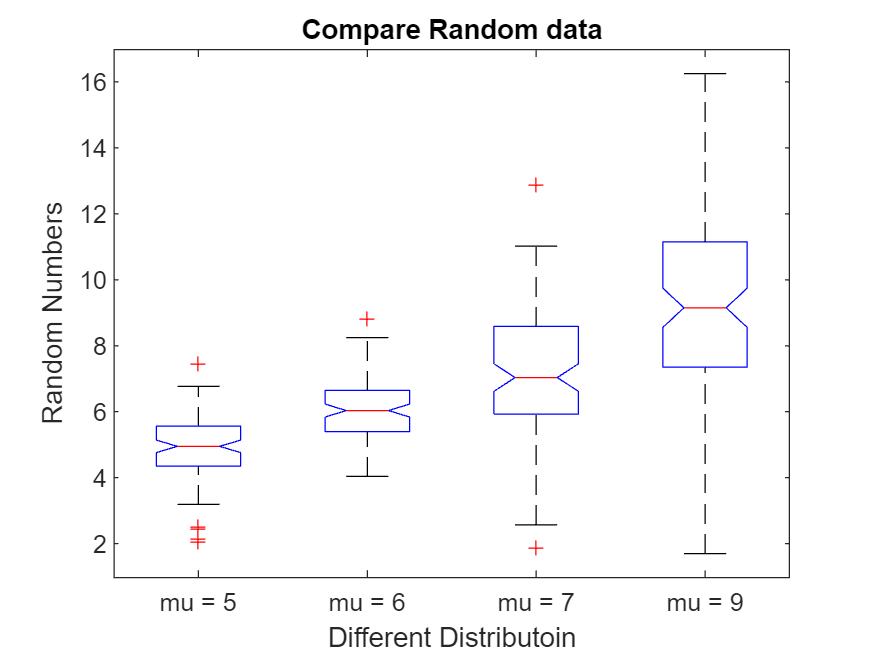


boxplot([x1, x2, x3, x4],'Labels', {'mu = 5', 'mu = 6', 'mu = 7', 'mu = 9'},'Notch','on')
title("Compare Random data")
xlabel('Different Distributoin')
ylabel('Random Numbers')

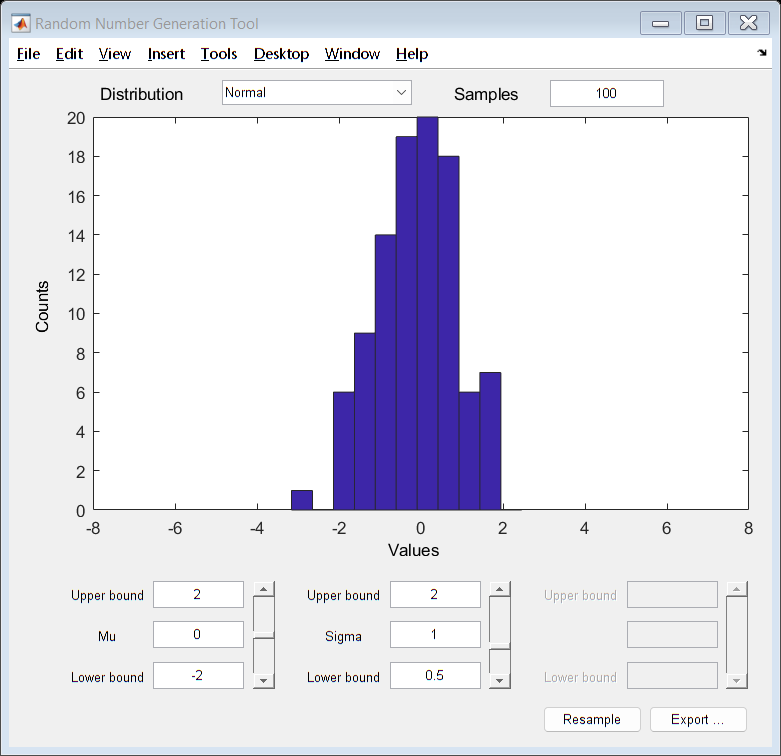

randtool

%doc cdfplot
x = randn(1,10000)

x =     0.7400   -0.0780   -0.1567   -1.1859   -0.7955   -0.2930   -1.8902    1.1428   -1.3688   -0.0697   -0.0610   -1.4475    0.2853    0.1001    0.6584    0.3729   -0.1875   -0.7796   -0.0335    0.6713    1.6917    1.1900   -1.8651   -0.8511   -0.1921   -0.4844    0.7117   -0.0042    0.1434   -1.7328   -0.1801   -1.7921   -1.3254   -0.6677   -1.5769    0.3358   -0.3782    2.3944    1.0536    0.2306   -1.5423    0.5754   -0.0498    0.4333    1.0996   -0.5398    0.0805   -0.0900   -1.1713   -0.9618


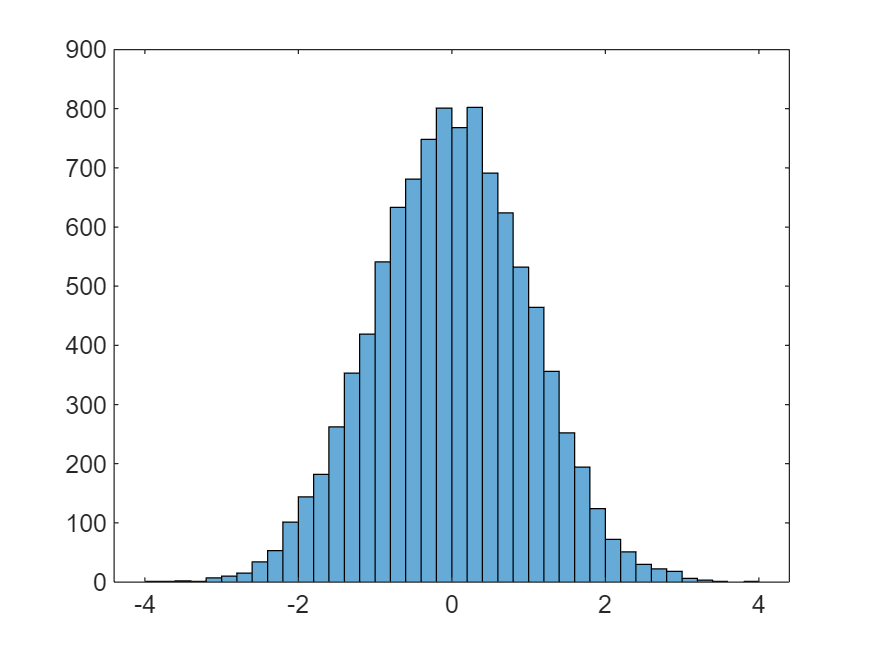

histogram(x)

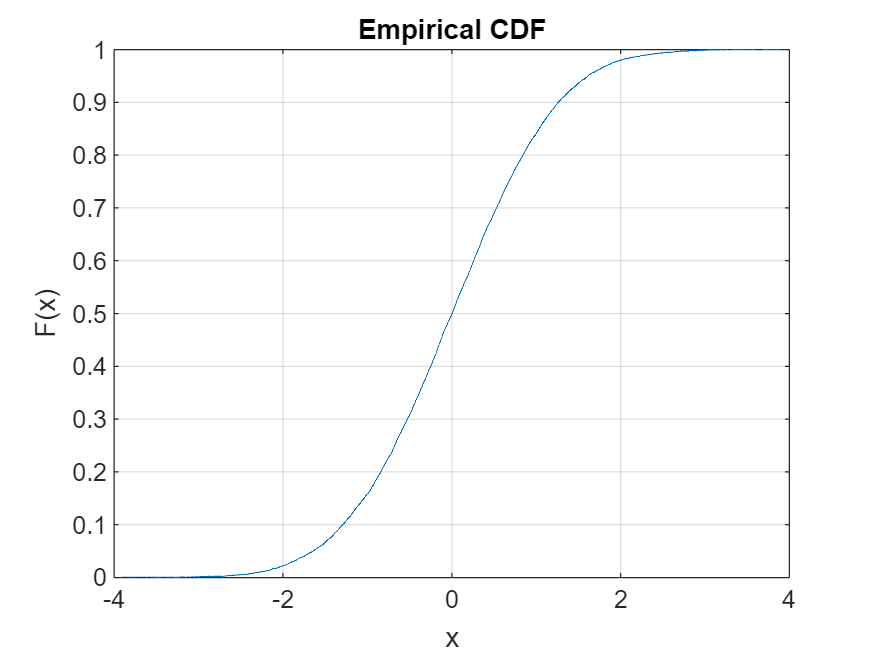

cdfplot(x)


% doc cdf

mu = 0;
sigma = 1;

cdf('Normal',0, mu, sigma)

ans = 0.5000


cdf('Normal',1, mu, sigma)

ans = 0.8413


cdf('Normal',2, mu, sigma)

ans = 0.9772

cdf('Normal',-1, mu, sigma)

ans = 0.1587

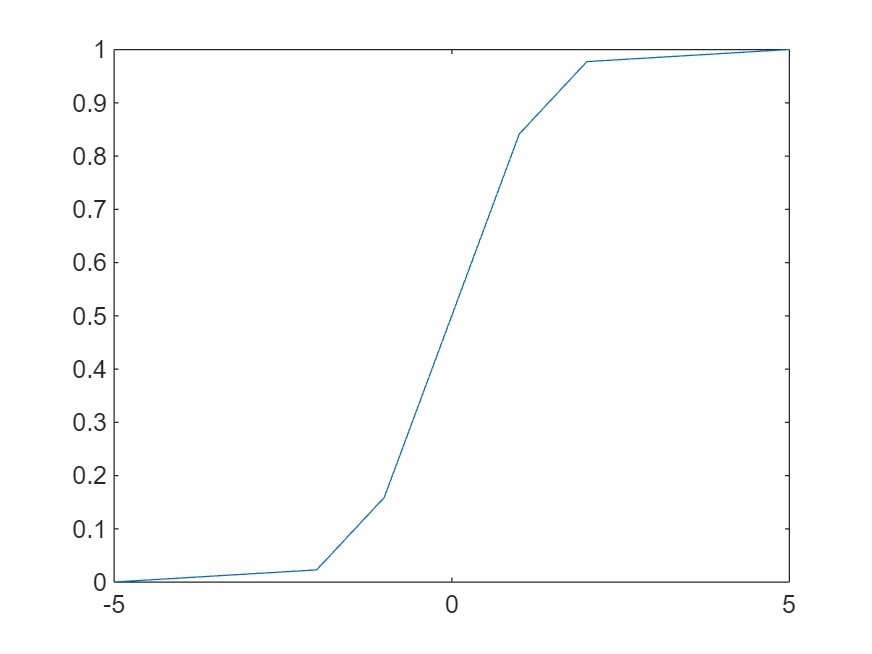


x = [-5, -2, -1, 0, 1, 2, 5];
y = cdf('Normal',x, mu, sigma);
plot(x,y)

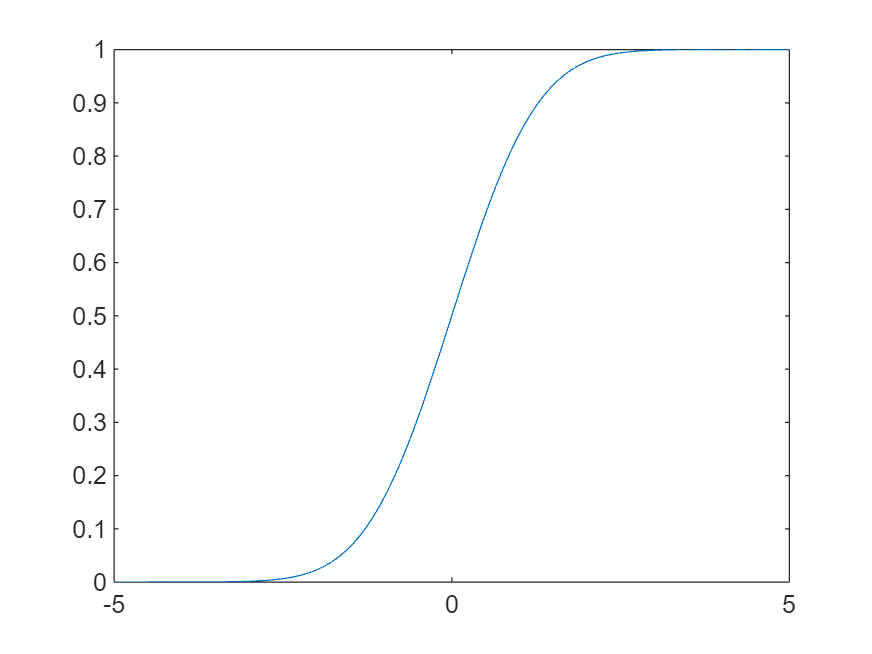


x = linspace(-5,5,100);
y = cdf('Normal',x, mu, sigma);
plot(x,y)

x = randn(1,10000)

x =    -0.9421   -0.5593    0.4028    1.0337    0.1520    0.2185   -1.6111   -1.6217   -0.8955   -2.2275    0.2708    0.0055   -0.6396    0.1580    0.0261    1.8445    2.5187    1.1209    0.3935    0.2884    0.5342   -0.1797   -0.3310    0.7952   -0.8270    0.7626   -0.2127   -0.1633    0.2749   -3.1715    0.5723    1.4282   -1.3511    0.3390   -0.6344    1.8371    0.1728   -2.3279    0.1272    1.4708    1.3171    0.5851   -0.2428    0.0050    0.8618   -0.9584    0.2874   -2.4708    0.0423    0.1458


dfittool

Least-Square Regression

clc
clear
close all

x = linspace(0,10);
y = 2*x + 3 + randn(size(x));
scatter(x,y)
hold on

p = polyfit(x,y,1)

p =     1.9730    3.1666


y1 = polyval(p,x)

y1 =     3.1666    3.3659    3.5652    3.7645    3.9638    4.1631    4.3624    4.5617    4.7610    4.9602    5.1595    5.3588    5.5581    5.7574    5.9567    6.1560    6.3553    6.5546    6.7538    6.9531    7.1524    7.3517    7.5510    7.7503    7.9496    8.1489    8.3481    8.5474    8.7467    8.9460    9.1453    9.3446    9.5439    9.7432    9.9425   10.1417   10.3410   10.5403   10.7396   10.9389   11.1382   11.3375   11.5368   11.7361   11.9353   12.1346   12.3339   12.5332   12.7325   12.9318


plot(x,y1,'LineWidth',2)

p = polyfit(x,y,2)

p =     0.0146    1.8269    3.4077


y1 = polyval(p,x)

y1 =     3.4077    3.5924    3.7774    3.9626    4.1482    4.3341    4.5202    4.7067    4.8935    5.0805    5.2679    5.4556    5.6435    5.8318    6.0203    6.2092    6.3983    6.5878    6.7775    6.9676    7.1579    7.3486    7.5395    7.7308    7.9223    8.1141    8.3063    8.4987    8.6914    8.8844    9.0778    9.2714    9.4653    9.6595    9.8541   10.0489   10.2440   10.4394   10.6351   10.8311   11.0274   11.2240   11.4209   11.6181   11.8156   12.0134   12.2115   12.4099   12.6086   12.8076


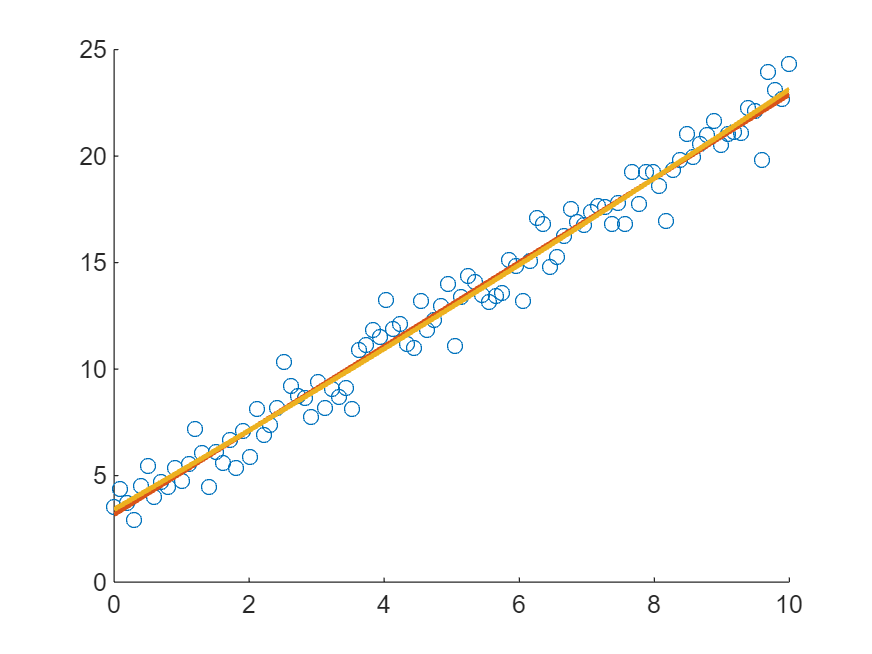

plot(x,y1,'LineWidth',2)

hold off

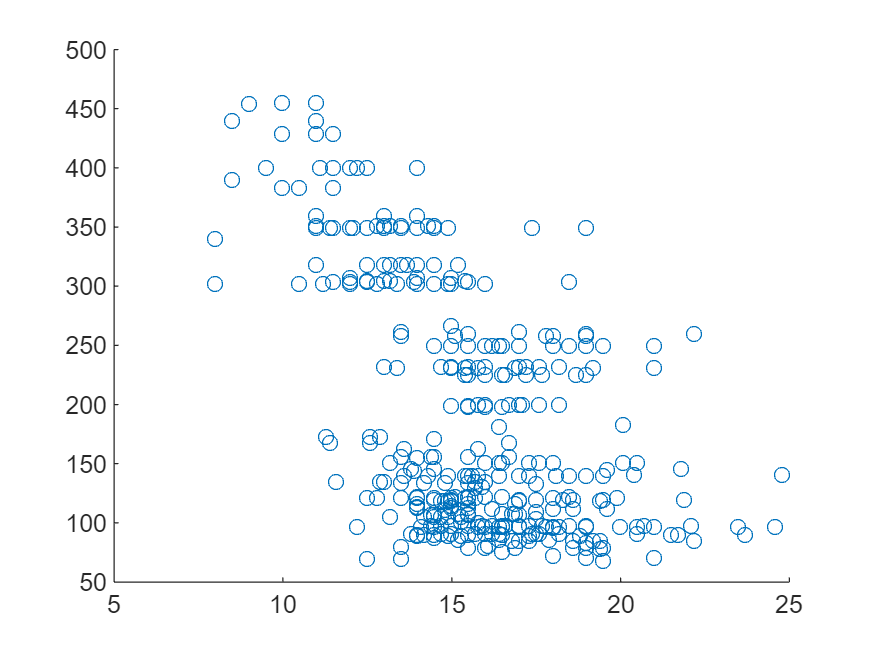

clc
clear 
close all
%doc load
Data = load('carbig.mat');
x = Data.Acceleration;
y = Data.Displacement;

scatter(x,y)

X = sortrows([x,y]);
x = X(:,1);
y = X(:,2);

scatter(x,y)
hold on
p = polyfit(x,y,1);
y1 = polyval(p,x);
plot(x,y1, 'LineWidth', 2)


p = polyfit(x,y,2);
y2 = polyval(p,x);
plot(x,y2, 'LineWidth', 2)


p = polyfit(x,y,10);
p(1)

ans = -7.8248e-07

p(2)

ans = 1.4949e-04

p(3)

ans = -0.0125

p(4)

ans = 0.5980

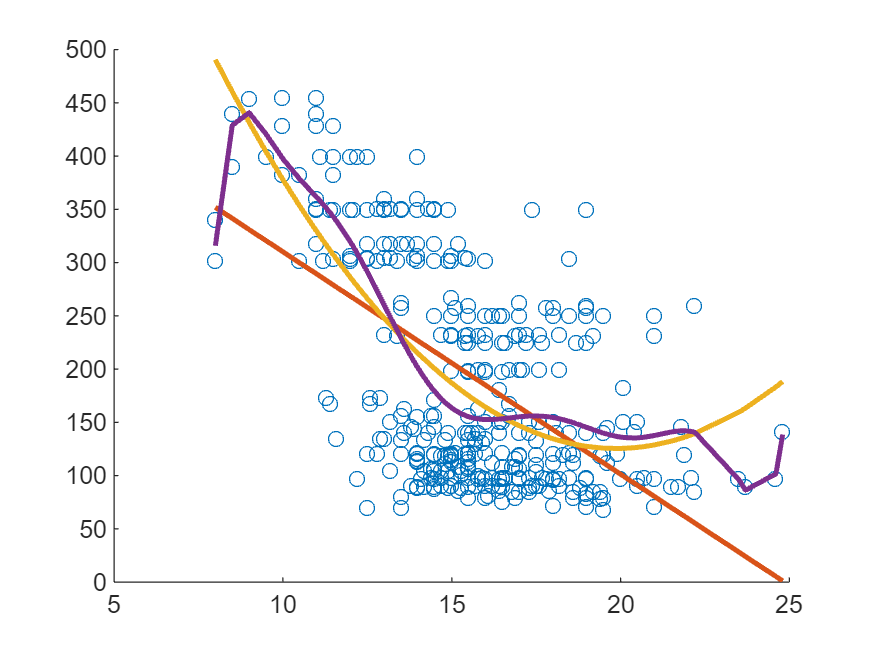

y3 = polyval(p,x);
plot(x,y3, 'LineWidth', 2)
hold off

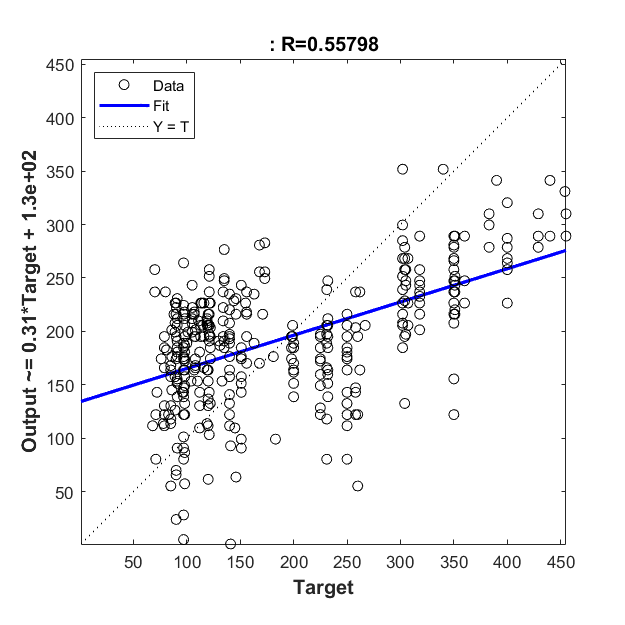



plotregression(y,y1)

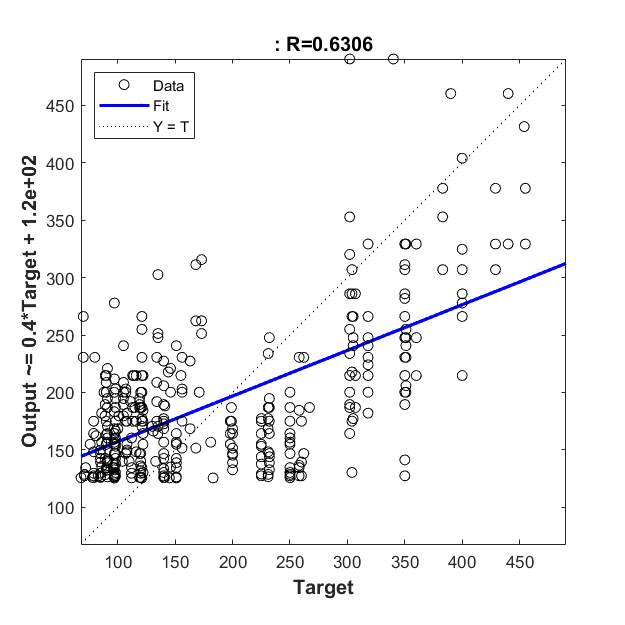

plotregression(y,y2)

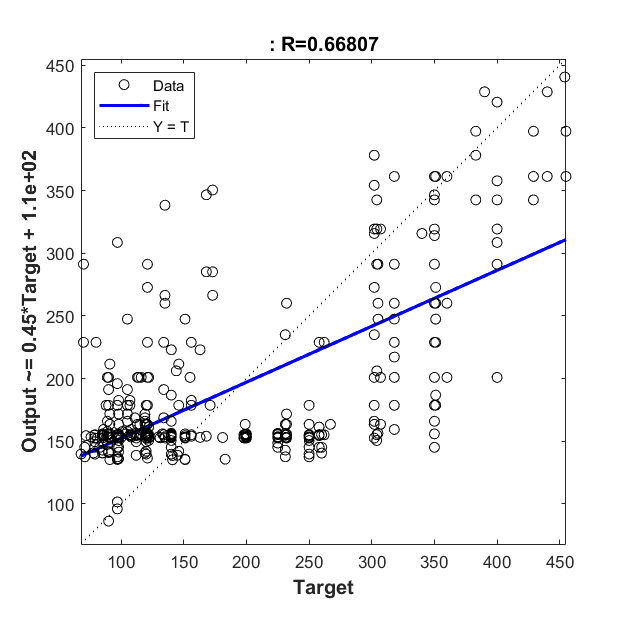

plotregression(y,y3)

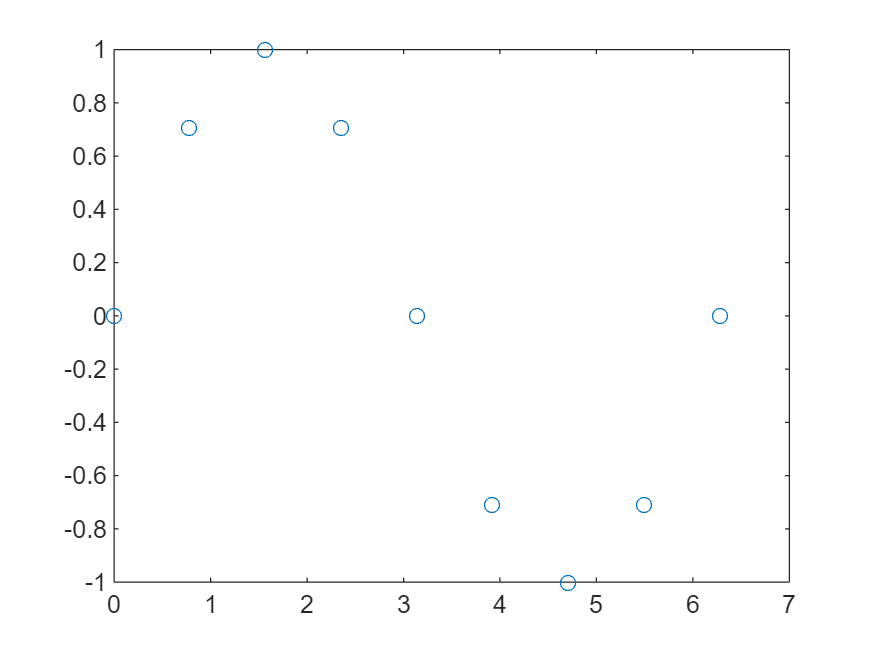

clc
clear
close all

x = 0:pi/4:2*pi;
y = sin(x);

plot(x,y,'o')

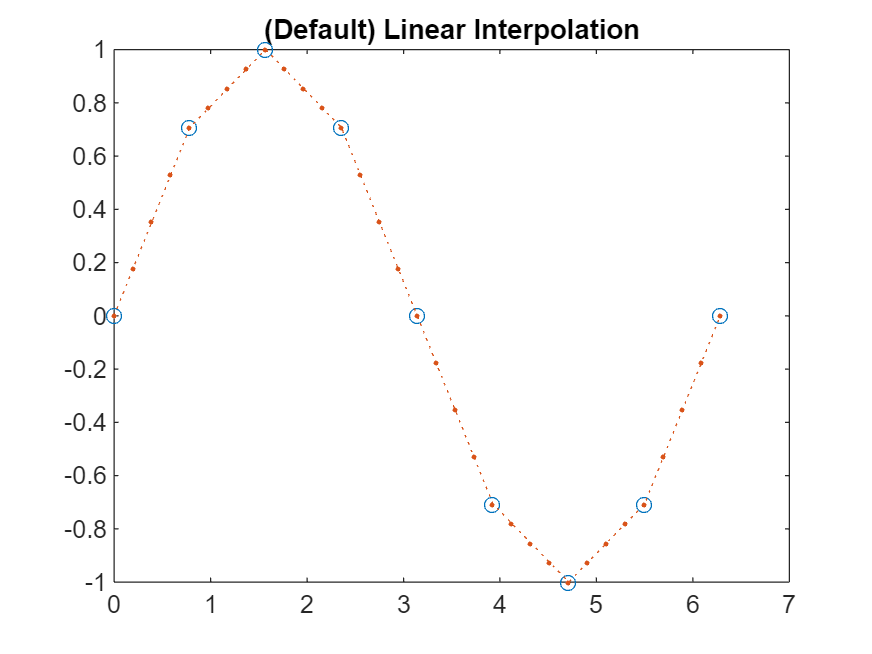


doc interp1

X = 0:pi/16:2*pi;
y1 = interp1(x,y,X);
plot(x,y,'o',X,y1,':.')
title('(Default) Linear Interpolation')

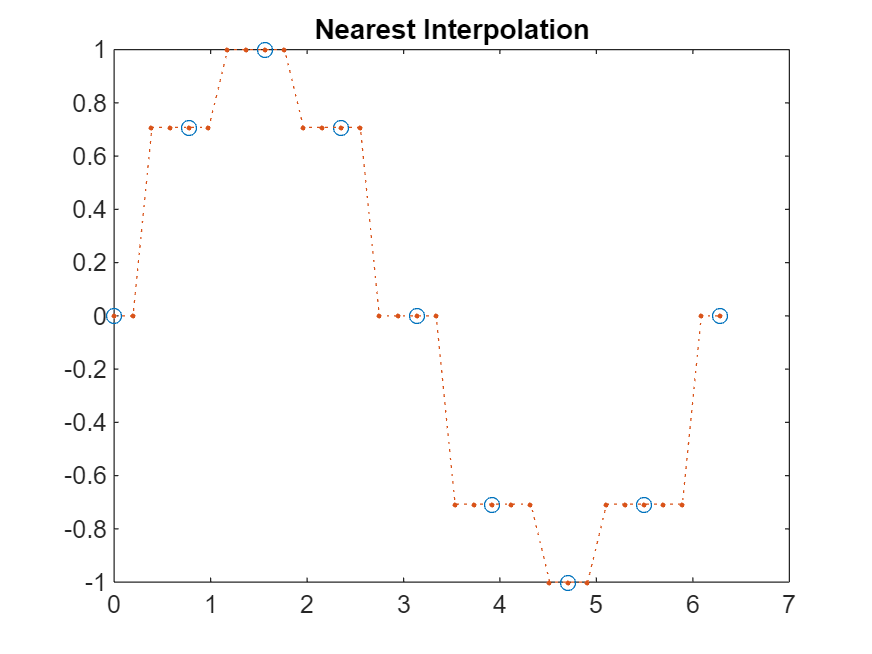


y2 = interp1(x,y,X,'nearest');
plot(x,y,'o',X,y2,':.')
title('Nearest Interpolation')

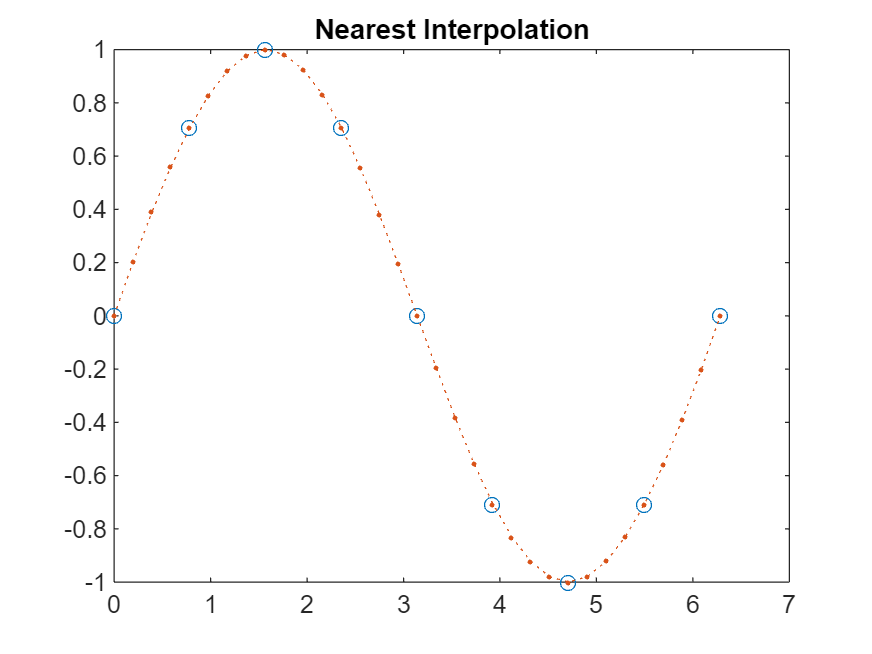



y3 = interp1(x,y,X,'spline');
plot(x,y,'o',X,y3,':.')
title('Spline Interpolation')

y4 = spline(x,y,X)

y4 =          0    0.1668    0.3244    0.4707    0.6035    0.7208    0.8205    0.9002    0.9581    0.9918    0.9993    0.9797    0.9346    0.8655    0.7745    0.6631    0.5341    0.3913    0.2387    0.0802   -0.0802   -0.2387   -0.3913   -0.5341   -0.6631   -0.7745   -0.8655   -0.9346   -0.9797   -0.9993   -0.9918   -0.9581   -0.9002   -0.8205   -0.7208   -0.6035   -0.4707   -0.3244   -0.1668   -0.0000


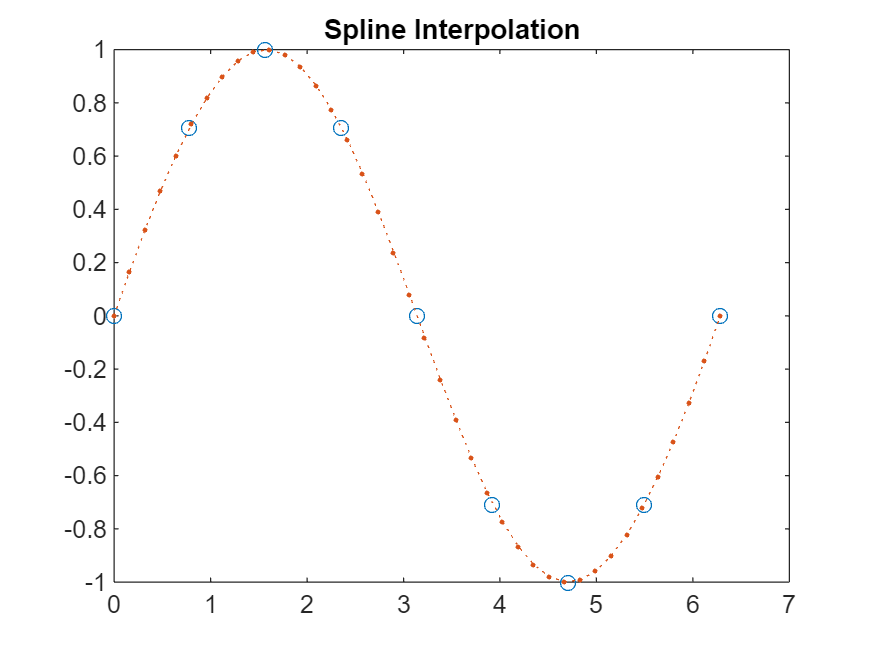

plot(x,y,'o',X,y4,':.')
title('Spline Interpolation')


y4 = spline(x,y)

y4 = struct with fields:
      form: 'pp'
    breaks: [0 0.7854 1.5708 2.3562 3.1416 3.9270 4.7124 5.4978 6.2832]
     coefs: [8×4 double]
    pieces: 8
     order: 4
       dim: 1

ppval(y4,3)

ans = 0.1407

X = linspace(0,2*pi,40);
Y = ppval(y4,X)

Y =          0    0.1668    0.3244    0.4707    0.6035    0.7208    0.8205    0.9002    0.9581    0.9918    0.9993    0.9797    0.9346    0.8655    0.7745    0.6631    0.5341    0.3913    0.2387    0.0802   -0.0802   -0.2387   -0.3913   -0.5341   -0.6631   -0.7745   -0.8655   -0.9346   -0.9797   -0.9993   -0.9918   -0.9581   -0.9002   -0.8205   -0.7208   -0.6035   -0.4707   -0.3244   -0.1668   -0.0000


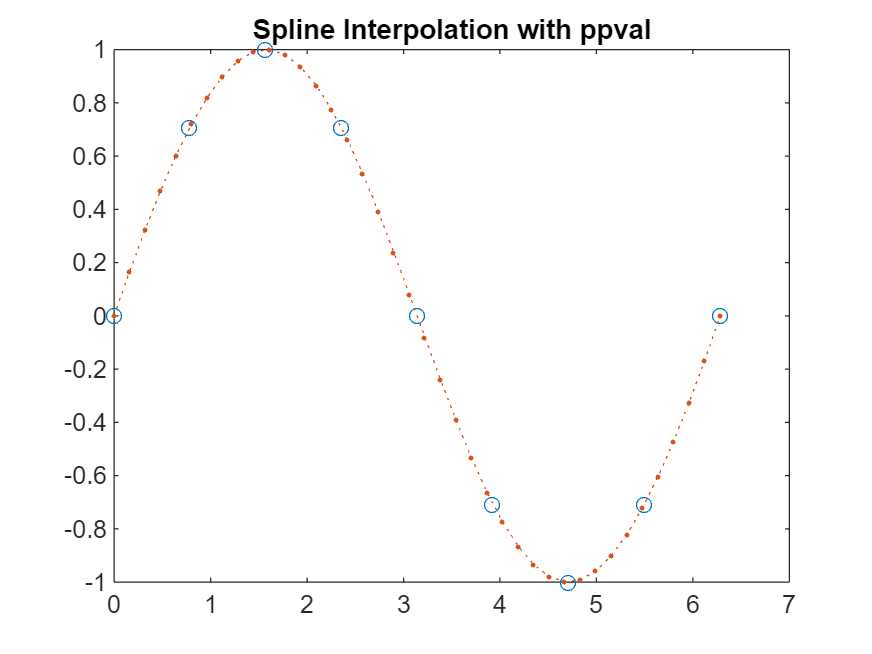

plot(x,y,'o',X,Y,':.')
title('Spline Interpolation with ppval')


y5 = pchip(x,y)

y5 = struct with fields:
      form: 'pp'
    breaks: [0 0.7854 1.5708 2.3562 3.1416 3.9270 4.7124 5.4978 6.2832]
     coefs: [8×4 double]
    pieces: 8
     order: 4
       dim: 1

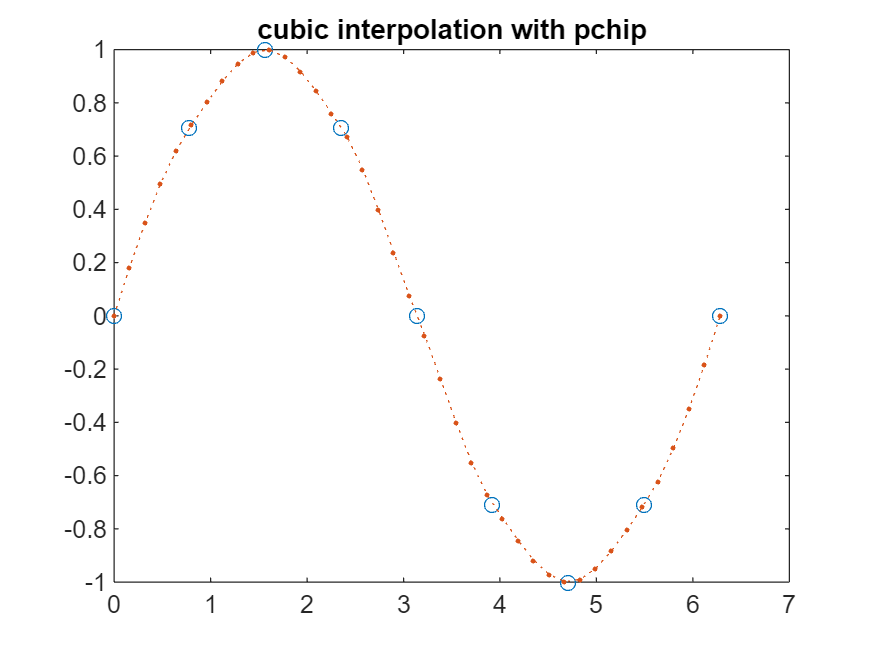

Y = ppval(y5,X);
plot(x,y,'o',X,Y,':.')
title('cubic interpolation with pchip')


y5.breaks

ans =          0    0.7854    1.5708    2.3562    3.1416    3.9270    4.7124    5.4978    6.2832


y5.coefs

ans =    -0.1771   -0.1967    1.1640         0
   -0.3541    0.0815    0.5274    0.7071
    0.3541   -0.7530         0    1.0000
    0.6046   -0.9496   -0.5274    0.7071
    0.6046   -0.4748   -0.9003    0.0000
    0.3541   -0.0815   -0.5274   -0.7071
   -0.3541    0.7530         0   -1.0000
   -0.1771    0.6139    0.5274   -0.7071




breaks = [0 4 10 15]

breaks =      0     4    10    15


coefs = [0 1 -1 1 1; 0 0 1 -2 53; -1 6 1 4 77]

coefs =      0     1    -1     1     1
     0     0     1    -2    53
    -1     6     1     4    77



y6 = mkpp(breaks,coefs)

y6 = struct with fields:
      form: 'pp'
    breaks: [0 4 10 15]
     coefs: [3×5 double]
    pieces: 3
     order: 5
       dim: 1


ppval(y6,2)

ans = 7

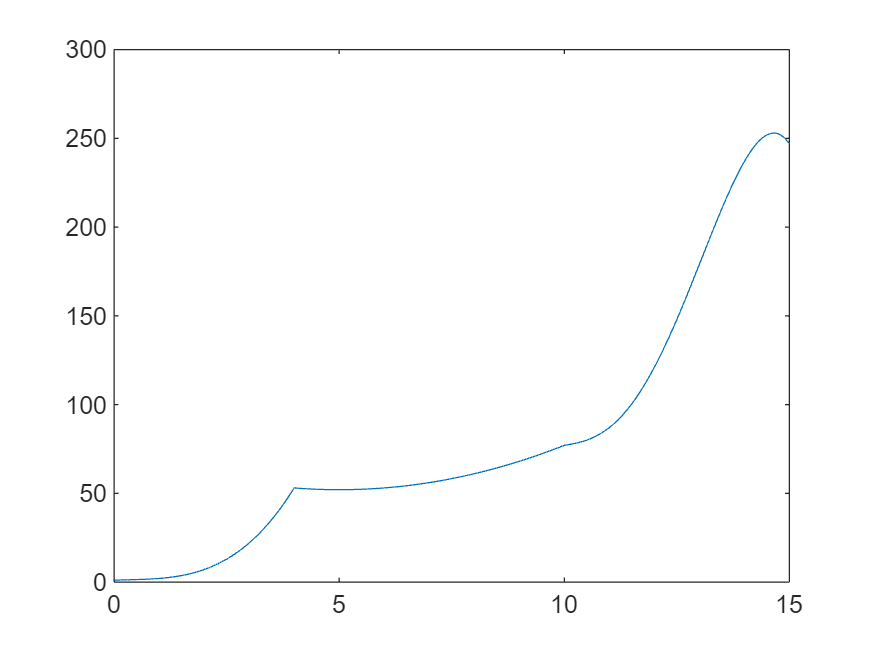

x = 0:0.1:15;
plot(x,ppval(y6,x))

[X, Y] = meshgrid(-3:1:3)

X =     -3    -2    -1     0     1     2     3
    -3    -2    -1     0     1     2     3
    -3    -2    -1     0     1     2     3
    -3    -2    -1     0     1     2     3
    -3    -2    -1     0     1     2     3
    -3    -2    -1     0     1     2     3
    -3    -2    -1     0     1     2     3


Y =     -3    -3    -3    -3    -3    -3    -3
    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -1
     0     0     0     0     0     0     0
     1     1     1     1     1     1     1
     2     2     2     2     2     2     2
     3     3     3     3     3     3     3


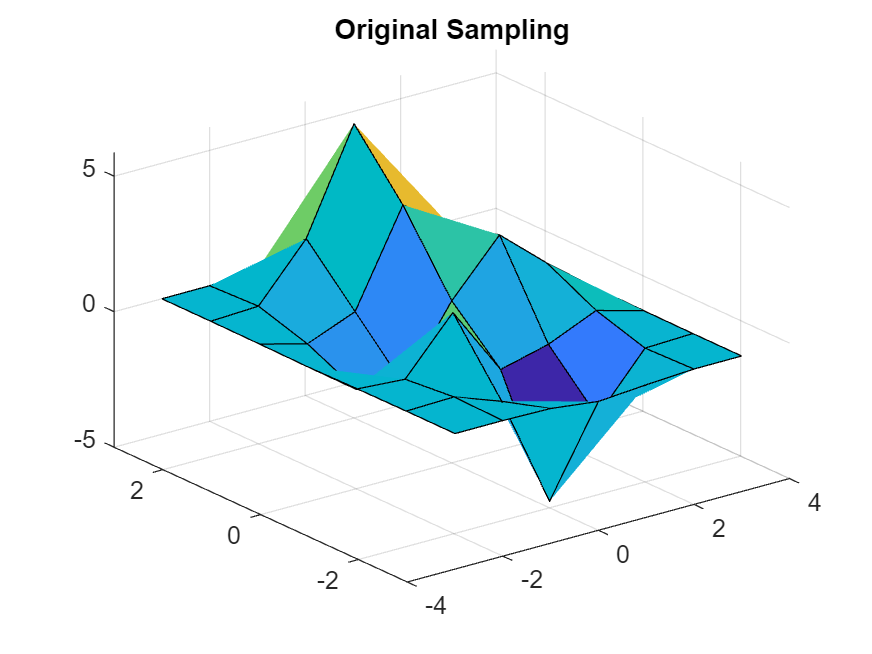

V = peaks(X,Y);

surf(X,Y,V)
title('Original Sampling')

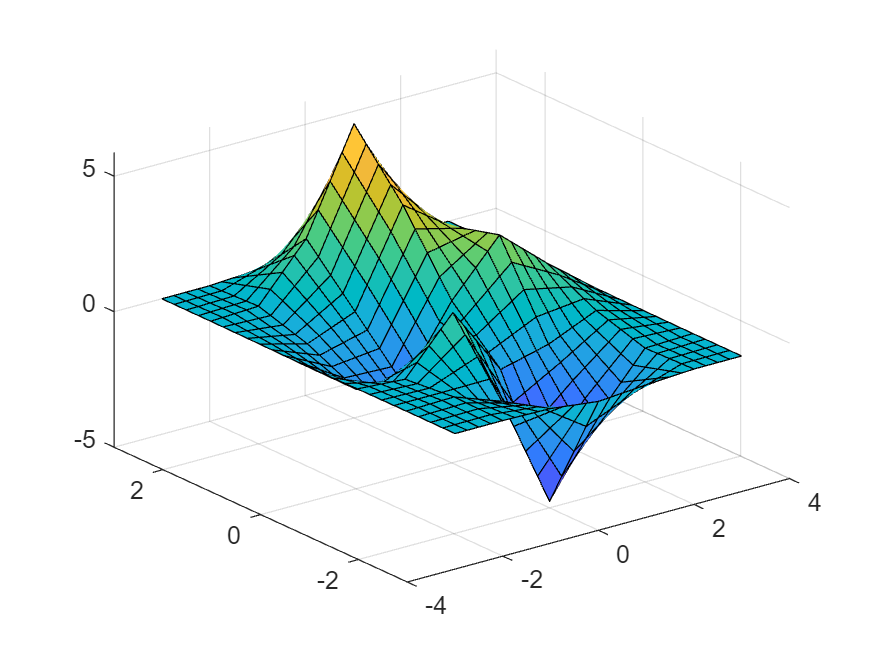


[Xq, Yq] = meshgrid(-3:0.25:3);
Vq = interp2(X,Y,V,Xq,Yq);
surf(Xq,Yq,Vq)